clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

species='Humans'; 

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 3; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};
allparietal_numbers=1:7;
allparietal_labels={'IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
allfrontal_numbers=1:2;
allfrontal_labels={'FEF','IFS'};
allLGN_numbers = 1;
allLGN_labels={'LGN'};
% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois=1:6; EVCcolor=[0 0 1];
V4rois=7; V4color=[1 0 1];
ventralrois=8:11; ventralcolor=[1 0 0];
dorsalrois=12:14; dorsalcolor=[1 .6 0]; % added V7, idk if that's right
lateralrois=15:18; lateralcolor=[0 1 0];
parietalrois=19:25; parietalcolor=[0 1 1];
frontalrois=26:27; frontalcolor=[.5 .1 .5];
LGNrois=28; LGNcolor=[1 1 0];
allrois = {EVCrois;V4rois;ventralrois;dorsalrois;lateralrois;parietalrois;frontalrois;LGNrois};
all_labels=[allvisual_labels, allparietal_labels, allfrontal_labels, allLGN_labels];
use_colorscale=[repmat(EVCcolor,length(EVCrois),1);...
    repmat(V4color,length(V4rois),1);...
    repmat(ventralcolor,length(ventralrois),1);...
    repmat(dorsalcolor,length(dorsalrois),1);...
    repmat(lateralcolor,length(lateralrois),1);...
    repmat(parietalcolor,length(parietalrois),1);...
    repmat(frontalcolor,length(frontalrois),1);...
    repmat(LGNcolor,1,1)];
use_colorscale_unique = unique(use_colorscale,'stable','rows');
use_colorscale_inv = flipud(use_colorscale);

nodearea_smoothwm_col=2;
nodearea_pial_col=3;

% This should be a more efficient way of filtering the directories:
files = dir(data_dir);
names = {files.name}; 
dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
subjs=names(dirFlags);
norois=[];

% retino_surfacearea outputs are 1x2 cells (hemispheres) each 18x62 (brain area x
% subject), total_surfacearea is sum of all brain areas 1x2 cell each 1x62
[retino_surfacearea_total,retino_surfacearea_smoothwm,retino_surfacearea_pial,...
    parietal_surfacearea_total,parietal_surfacearea_smoothwm,parietal_surfacearea_pial,...
    frontal_surfacearea_total,frontal_surfacearea_smoothwm,frontal_surfacearea_pial,...
    LGN_surfacearea] = getSubjData_human(subjs,species,plot_indiv_subj,...
    allvisual_numbers,allparietal_numbers,allfrontal_numbers,nodearea_smoothwm_col,nodearea_pial_col);

No allparietal in abma
No allfrontal in abma
No allparietal in amar
No allfrontal in amar
No allparietal in ccha
No allfrontal in ccha
No allparietal in csai
No allfrontal in csai
No allparietal in dbou
No allfrontal in dbou
No allparietal in ebou
No allfrontal in ebou
No allparietal in ebow
No allfrontal in ebow
No allparietal in fper
No allfrontal in fper
No allfrontal in gdet
No allparietal in heyu
No allfrontal in heyu
No allparietal in ifie
No allfrontal in ifie
No allparietal in jche
No allfrontal in jche
No allparietal in jfan
No allfrontal in jfan
No allparietal in jwhi
No allfrontal in jwhi
No allparietal in lsil
No allfrontal in lsil
No allparietal in lwan
No allfrontal in lwan
No allparietal in mfog
No allfrontal in mfog
No allparietal in mkug
No allfrontal in mkug
No allparietal in mlob
No allfrontal in mlob
No allparietal in skhe
No allfrontal in skhe
No allparietal in tsco
No allfrontal in tsco


area_metric = 3;
for i = 1:2
    surfacearea_total{i} = retino_surfacearea_total{i} + parietal_surfacearea_total{i} + frontal_surfacearea_total{i};
    surfacearea_smoothwm{i} = [retino_surfacearea_smoothwm{i};parietal_surfacearea_smoothwm{i};frontal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [retino_surfacearea_pial{i};parietal_surfacearea_pial{i};frontal_surfacearea_pial{i}];
end

total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);
surfacearea_avg{1} = [surfacearea_avg{1};LGN_surfacearea{1}];
surfacearea_avg{2} = [surfacearea_avg{2};LGN_surfacearea{2}];

if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea = surfacearea_avg;
end

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis(7,:);

retino_surfacearea_bothhemis_combinedV123 = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(8:end,:)];

%combined hemis V1
normv1_human = retino_surfacearea_bothhemis_combinedV123./V1_bothhemis_combined;

ventral_combined_human = mean(normv1_human(ventralrois-3,:),1);
dorsal_combined_human = mean(normv1_human(dorsalrois-3,:),1);
lateral_combined_human = mean(normv1_human(lateralrois-3,:),1);
parietal_combined_human = mean(normv1_human(parietalrois-3,:),1);
frontal_combined_human = mean(normv1_human(frontalrois-3,:),1);
LGN_combined_human = mean(normv1_human(LGNrois-3,:),1);

normv1_combined_human = [normv1_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human;frontal_combined_human;LGN_combined_human];

use_colorscale=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor;LGNcolor];
use_colorscale_unique = unique(use_colorscale,'stable','rows');
use_colorscale_inv = flipud(use_colorscale);

alllabels_combined = {'V1','V2/3','V4','Ventral','Dorsal','Lateral','Parietal','Frontal','LGN'};


% % using stepwise linear regression to look at relationship between V1-4 & MT
% X = [V2_bothhemis_combined;V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(17,:)]';
% y = V1_bothhemis_combined';
% mdl = stepwiselm(X,y,'PEnter',0.05,'PredictorVars',{'V2','V3','V4','MT'})
% 
% X = [V3_bothhemis_combined;V1_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(17,:)]';
% y = V2_bothhemis_combined';
% mdl = stepwiselm(X,y,'PEnter',0.05,'PredictorVars',{'V1','V3','V4','MT'})
% 
% X = [V1_bothhemis_combined;V2_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(17,:)]';
% y = V3_bothhemis_combined';
% mdl = stepwiselm(X,y,'PEnter',0.05,'PredictorVars',{'V1','V2','V4','MT'})
% 
% X = [V1_bothhemis_combined;V2_bothhemis_combined;V3_bothhemis_combined;surfacearea_bothhemis(17,:)]';
% y = V4_bothhemis_combined';
% mdl = stepwiselm(X,y,'PEnter',0.05,'PredictorVars',{'V1','V2','V3','MT'})
% 
% X = [V1_bothhemis_combined;V2_bothhemis_combined;V3_bothhemis_combined;V4_bothhemis_combined]';
% y = surfacearea_bothhemis(17,:)';
% mdl = stepwiselm(X,y,'PEnter',0.09,'PredictorVars',{'V1','V2','V3','V4'})

species='Monks'; 

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 1; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,100,101,102,103,52,53,54,55,56];
all_labels={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       
EVCrois=1:6; EVCcolor=[0 0 1];
V4rois=7:10; V4color=[1 0 1];
ventralrois=11:15; ventralcolor=[1 0 0];
dorsalrois=16:17; dorsalcolor=[1 .6 0];
lateralrois=18:22; lateralcolor=[0 1 0];
parietalrois=23:26; parietalcolor=[0 1 1];
allrois = {EVCrois;V4rois;ventralrois;dorsalrois;parietalrois;lateralrois};
use_colorscale=[repmat(EVCcolor,length(EVCrois),1);...
    repmat(V4color,length(V4rois),1);...
    repmat(ventralcolor,length(ventralrois),1);...
    repmat(dorsalcolor,length(dorsalrois),1);...
    repmat(lateralcolor,length(lateralrois),1);...
    repmat(parietalcolor,length(parietalrois),1)];
use_colorscale_unique = unique(use_colorscale,'stable','rows');

% This should be a more efficient way of filtering the directories:
files = dir(data_dir);
names = {files.name}; 
dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
subjs=names(dirFlags);
norois=[];

[retino_surfacearea_total,retino_surfacearea_smoothwm,retino_surfacearea_pial] = getSubjData( ...
subjs,species,plot_indiv_subj,allvisual_numbers,nodearea_smoothwm_col,nodearea_pial_col);

Error Read_1D:
 ./Monks/baby5/rh.thickness.1D.dset not found
Error Read_1D:
 ./Monks/baby5/lh.thickness.1D.dset not found



for i = 1:2
    surfacearea_total{i} = retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = retino_surfacearea_pial{i};
end

total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea = surfacearea_avg;
end

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas



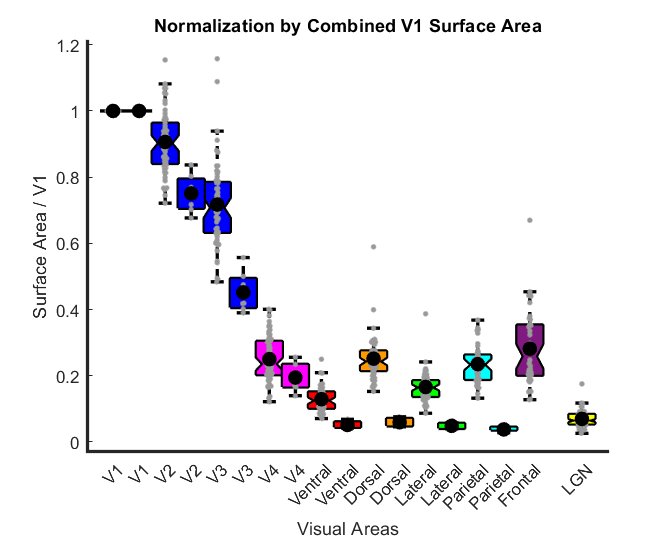

V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis(9:10,:),1);

retino_surfacearea_bothhemis_combinedV123 = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis(11:end,:)];

%combined hemis V1
normv1_monkey = retino_surfacearea_bothhemis_combinedV123./V1_bothhemis_combined;

V4_combined_monkey = mean(normv1_monkey(4:5,:),1);
ventral_combined_monkey = mean(normv1_monkey(ventralrois-5,:),1);
dorsal_combined_monkey = mean(normv1_monkey(dorsalrois-5,:),1);
lateral_combined_monkey = mean(normv1_monkey(lateralrois-5,:),1);
parietal_combined_monkey = mean(normv1_monkey(parietalrois-5,:),1);

normv1_combined_monkey = [normv1_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];


use_colorscale=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor;LGNcolor];
use_colorscale_unique = unique(use_colorscale,'stable','rows');
use_colorscale_inv = flipud(use_colorscale);

alllabels_combined = {'V1','V1','V2','V2','V3','V3','V4','V4','Ventral','Ventral','Dorsal','Dorsal','Lateral','Lateral','Parietal','Parietal','Frontal','','LGN'};


figure
hold on
h1=boxplot(normv1_combined_human','positions',1:2:size(normv1_combined_human,1)*2,'notch','on','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(normv1_combined_human,1)
   patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
end
plotSpread(normv1_combined_human','xValues',1:2:size(normv1_combined_human,1)*2,'distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(normv1_combined_human,1)*2,nanmean(normv1_combined_human'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_human,1)+.5])

use_colorscale=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_unique = unique(use_colorscale,'stable','rows');
use_colorscale_inv = flipud(use_colorscale);

h2=boxplot(normv1_combined_monkey','positions',2:2:size(normv1_combined_monkey,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h2,{'linew'},{2})
h2 = findobj(gca,'Tag','Box');
for j=1:size(normv1_combined_monkey,1)
   patch(get(h2(j),'XData'),get(h2(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
end
plotSpread(normv1_combined_monkey','xValues',2:2:size(normv1_combined_monkey,1)*2,'distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(2:2:size(normv1_combined_monkey,1)*2,nanmean(normv1_combined_monkey'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_monkey,1)+.5])
hold on

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(alllabels_combined)],'xticklabel', alllabels_combined);
xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

ylim([0 1.2])
pngFileName = ('Normalization_CombinedV1.png');
fullFileName = fullfile(save_folder, pngFileName);
% saveas(gcf, fullFileName);